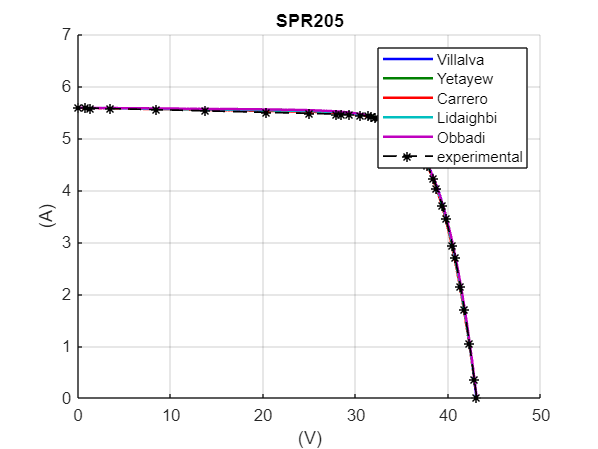

%Matriz para cambiar colores
clear all
newcolors = [0         0    1.0000
         0    0.5000         0
    1.0000         0         0
         0    0.7500    0.7500
    0.7500         0    0.7500
    0.7500    0.7500         0
    0.2500    0.2500    0.2500
         0.3500    0.7500    0.200
         0.4400    0.3500    0.300
          0    1    0];
colororder(newcolors);
clear all
hold on
%Ejemplo para el SPR205
Voc=43.062;
Isc=5.5807;
Imp=5.1280;
Vmp=35.079;
T=54.80;
Ns=72;
%Lectura excel
Ie= transpose(xlsread('SPR205.xlsx','1 kW','l11:l70'));
Ve= transpose(xlsread('SPR205.xlsx','1 kW','F11:F70'));
%Constantes físicas
q=1.60218*10^(-19);
K=1.38065*10^(-23);
Isc=Isc*G/Gd;
Imp=Imp*G/Gd;
%Lectura de los parámetros
Carrero=xlsread('Lecturaresults.xlsx','h35:l35');
Yetayew=xlsread('Lecturaresults.xlsx','h36:l36');
Lidaighbi=xlsread('Lecturaresults.xlsx','h37:l37');
Obbadi=xlsread('Lecturaresults.xlsx','h38:l38');
Villalva=xlsread('Lecturaresults.xlsx','h39:l39');
%Creación de la matriz 3d con los parámetros obtenidos con cada procedimiento
para(:,:,3)=Carrero;
para(:,:,2)=Yetayew;
para(:,:,4)=Lidaighbi;
para(:,:,5)=Obbadi;
para(:,:,1)=Villalva;
%Constantes físicas
q=1.60218*10^(-19);
K=1.38065*10^(-23);
%Cálculo Vth 
Vth=Ns*K*(T+273.15)/q;
for i=1:5
Rsh=para(1,2,i);
Iph=para(1,5,i);
Rs=para(1,1,i);
n=para(1,3,i);
Io=para(1,4,i);
clear x y
syms x y
f1=-y+Iph-Io*(exp((x+y*Rs)/(n*Vth))-1)-(x+y*Rs)/Rsh;
grid on
fimplicit(f1,[0 Voc+1 0 Isc+1],'LineWidth',1.5);
xlabel('(V)');
ylabel('(A)');
hold on
end
%Valores experimentales
plot(Ve,Ie,'--*k','LineWidth',1);
title('SPR205');
legend('Villalva','Yetayew','Carrero','Lidaighbi','Obbadi','experimental');

%El color de las gráficas salen diferentes al de mi TFG, se cambiaron
%después
